# Aliasing Example 1

Matlab file used for class demo conducted during session on sampling to illustrate the effects of aliasing AND the relationship between the DTFT and CTFT when the DT signal is obtained by sampling an analog CT signal.

A short recorded sample is effectively sampled at four different rates and played back to hear the effects of aliasing.

Adapted for EG-247 Signals and Systems by Dr Chris P. Jobling from an example by Prof. Charles A. Bouman, School of Electrical and Computer Engineering, Purdue University, West Lafayette.

Original file: [https://engineering.purdue.edu/VISE/ee438/demos/](https://engineering.purdue.edu/VISE/ee438/demos/)

clf
set(0,'defaultaxesfontsize',16);

audioFile = 'eg-247-message.wav';
[data,Fs] = audioread(audioFile);

plot data to cut off silence

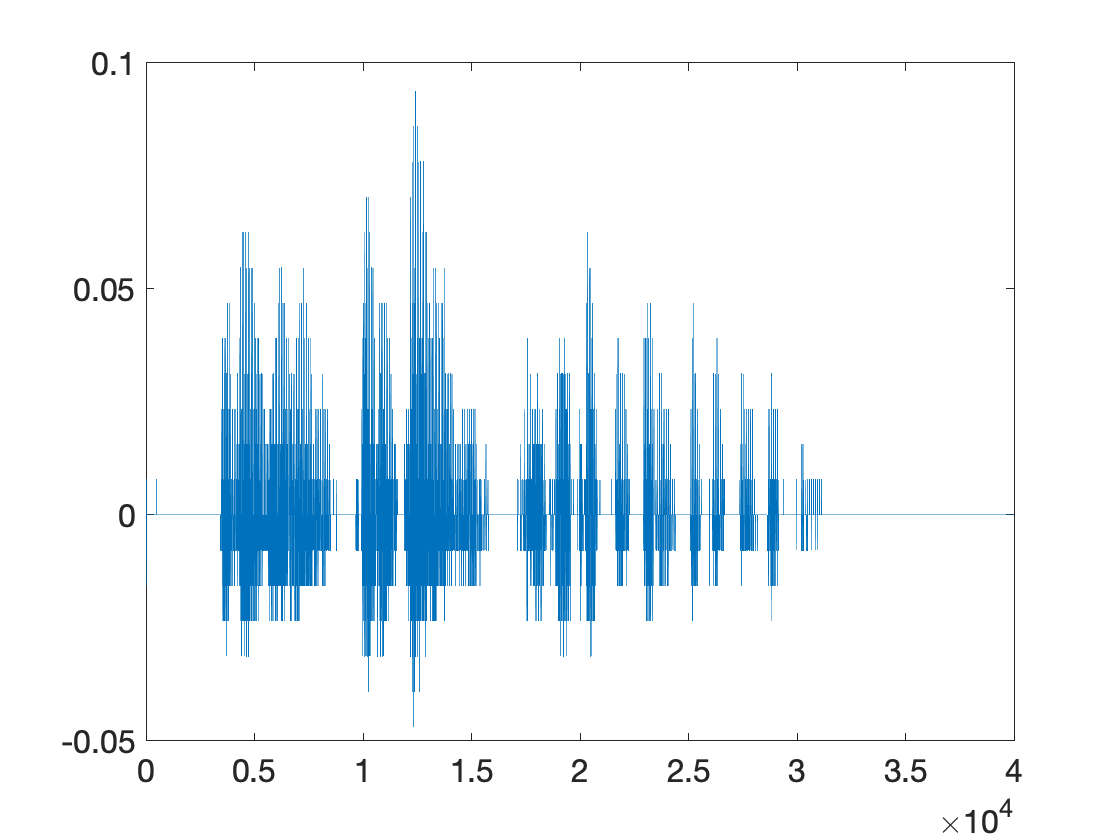

plot(data)

end1=3000;
end2=32000;
datar=data(end1:end2);
datar=data;
dsize=length(datar); 

compute 8192 point FFT to view spectrum of speech signal

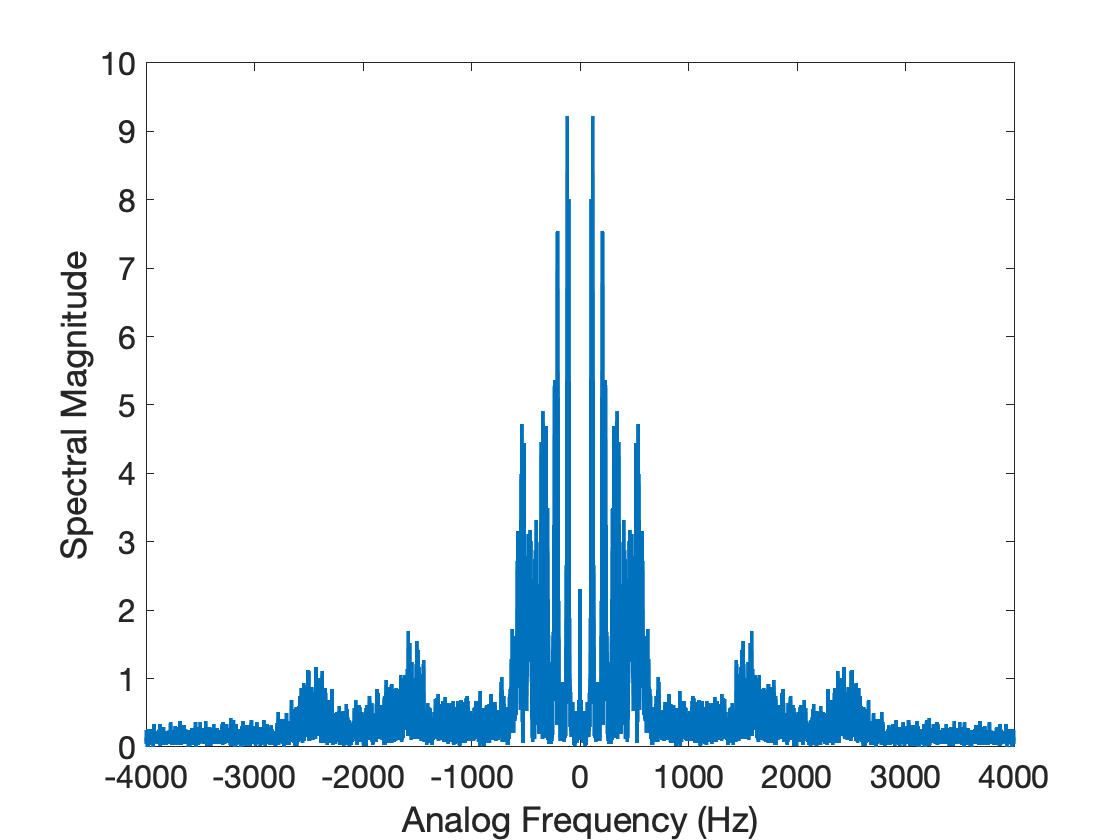

deltaf=Fs/8192;
freq=-Fs/2:deltaf:Fs/2-deltaf;
plot(freq,abs(fftshift(fft(datar,8192))),'linewidth',2)
xlabel('Analog Frequency (Hz)')
ylabel('Spectral Magnitude')

domega=2*pi/8192;
omega=-pi:domega:pi-domega;

Playback speech at original sampling rate of 8000 Hz.

soundsc(datar,Fs)

Reduce sampling rate by a factor of 2 through decimation and playback speech at sampling rate of 4000 Hz.

datar2=datar(1:2:dsize);
soundsc(datar2,Fs/2)

Reduce sampling rate by a factor of 3 through decimation and playback speech at sampling rate of 2667 Hz.

datar3=datar(1:3:dsize);
soundsc(datar3,round(Fs/3))

Reduce sampling rate by a factor of 4 through decimation and playback speech at sampling rate of 2000 Hz.

datar4=datar(1:4:dsize);
soundsc(datar4,Fs/4)

Compute via the FFT the DTFT of each of the four sampled versions of the original speech. Plot magnitude of each DTFT over $-\pi$ to $\pi \ldotp$

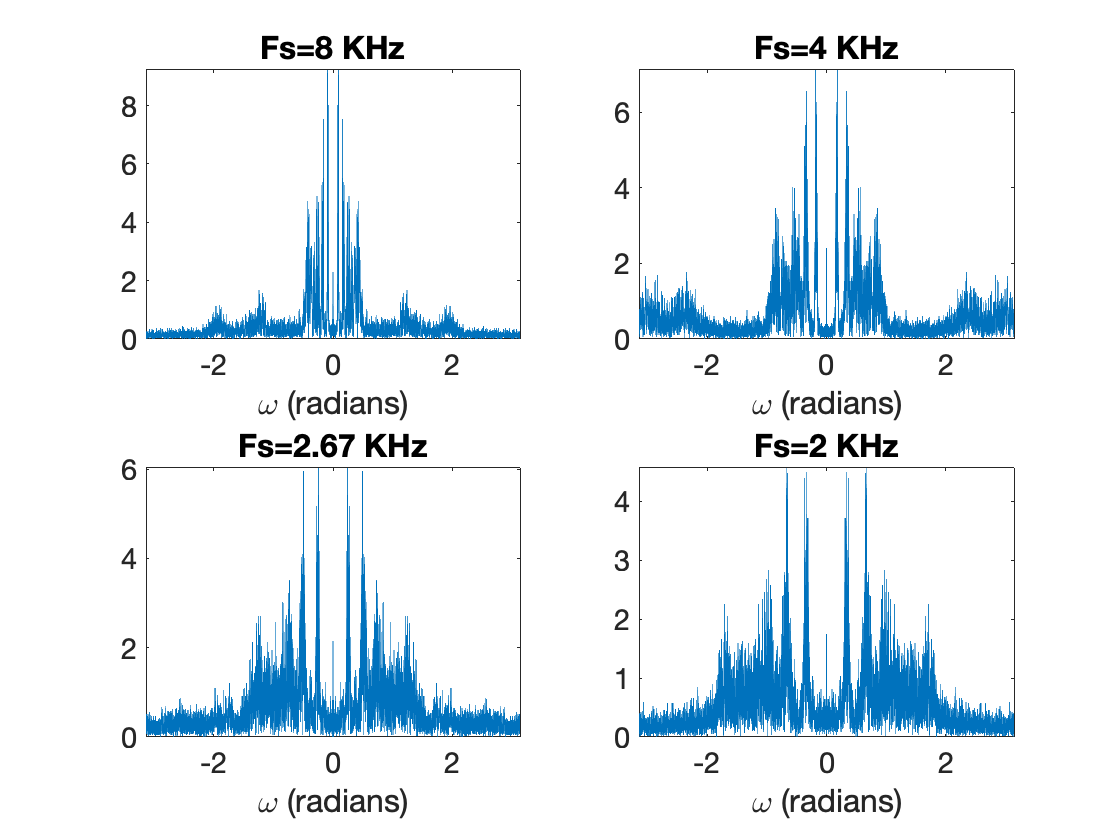

subplot(221)
dr1=abs(fftshift(fft(datar,8192)));
plot(omega,dr1)
axis([-pi pi 0 max(dr1)])
title('Fs=8 KHz')
xlabel('\omega (radians)')
subplot(222)
dr2=abs(fftshift(fft(datar2,8192)));
plot(omega,dr2)
axis([-pi pi 0 max(dr2)])
title('Fs=4 KHz')
xlabel('\omega (radians)')
subplot(223)
dr3=abs(fftshift(fft(datar3,8192)));
plot(omega,dr3)
axis([-pi pi 0 max(dr3)])
title('Fs=2.67 KHz')
xlabel('\omega (radians)')
subplot(224)
dr4=abs(fftshift(fft(datar4,8192)));
plot(omega,dr4)
axis([-pi pi 0 max(dr4)])
title('Fs=2 KHz')
xlabel('\omega (radians)')